clear; close all;

[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end


Beh = obj.BehavTable;


## Chemo effect

bins = .5:.001:3;
band_width = 0.12;
n_boot = 1000;
alpha_boot = 0.05;

kde_pdf = @(x) ksdensity(x, bins, 'Function', 'pdf', 'Bandwidth', band_width); % 
boot_pdf = @(x) bootci(n_boot, {kde_pdf, x}, 'type', 'cper', 'alpha', alpha_boot);


Port = [1 2];
Guided = [0 1];
Label = ["Control", "Chemo"];

ls = [":", "-"];
lw = [1.5, 1];
c = {GPSColor.Control, GPSColor.Treat};

id = cell(2,2,2);
hd = cell(2,2,2);
pd = cell(2,2,2);
pd_ci = cell(2,2,2);

for i = 1:2 % Port
    for j = 1:2 % Guided
        for k = 1:2 % Label
            disp([i j k]);
            id{i,j,k} = find(Beh.Cued==0 & Beh.PortCorrect==Port(i) & Beh.Guided==Guided(j) & Beh.Label==Label(k));
            hd{i,j,k} = Beh.HoldDuration(id{i,j,k});
            pd{i,j,k} = kde_pdf(hd{i,j,k});
            pd_ci{i,j,k} = boot_pdf(hd{i,j,k});
        end
    end
end


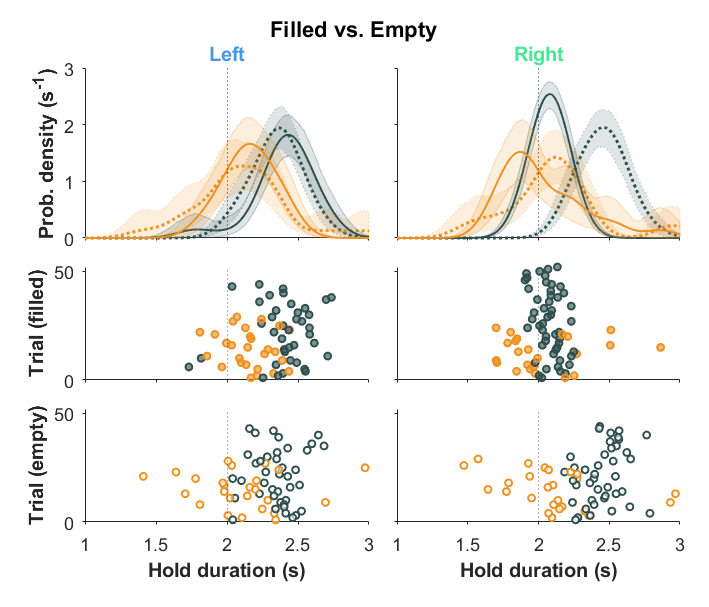

fig = figure(35); clf(35);
set(fig, 'Name', 'fill vs empty', 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12.5 10.7], 'Color', 'w');

% uicontrol('parent', fig, 'Style', 'text', 'units', 'centimeters', 'position', [1 fig.Position(4)-.75 fig.Position(3)-2 .5],...
%         'string', "Filled vs. Empty", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

.

ax_l_pdf = axes(fig, 'Units', 'centimeters', 'Position', [1.5 6.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
for j = 1:2 % Guided
    for k = 1:2 % Label
        xline(ax_l_pdf, 2, 'LineWidth', .5, 'LineStyle', ':');
        fill(ax_l_pdf, [bins flip(bins)], [pd_ci{1,j,k}(1,:) flip(pd_ci{1,j,k}(2,:))], 'y', ...
            'FaceColor', c{k}, 'FaceAlpha', 0.15, ...
            'EdgeColor', c{k}, 'EdgeAlpha', 0.3, ...
            'LineStyle', ls(j), 'LineWidth', .5*lw(j));
        plot(ax_l_pdf, bins, pd{1,j,k}, ...
            'color', c{k}, 'linewidth', lw(j), 'LineStyle', ls(j));
    end
end

ax_l_pdf.YLabel.String = "Prob. density (s^{-1})";
ax_l_pdf.YLabel.FontWeight = "bold";
ax_l_pdf.Title.String = "Left";
ax_l_pdf.Title.FontWeight = "bold";
ax_l_pdf.Title.Color = GPSColor.PortL;

set(ax_l_pdf, 'XLim', [1 3], 'XTickLabel', []);

%
ax_r_pdf = axes(fig, 'Units', 'centimeters', 'Position', [7 6.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
for j = 1:2 % Guided
    for k = 1:2 % Label
        xline(ax_r_pdf, 2, 'LineWidth', .5, 'LineStyle', ':');
        fill(ax_r_pdf, [bins flip(bins)], [pd_ci{2,j,k}(1,:) flip(pd_ci{2,j,k}(2,:))], 'y', ...
            'FaceColor', c{k}, 'FaceAlpha', 0.15, ...
            'EdgeColor', c{k}, 'EdgeAlpha', 0.3, ...
            'LineStyle', ls(j), 'LineWidth', .5*lw(j));
        plot(ax_r_pdf, bins, pd{2,j,k}, ...
            'color', c{k}, 'linewidth', lw(j), 'LineStyle', ls(j));
    end
end

ax_r_pdf.Title.String = "Right";
ax_r_pdf.Title.FontWeight = "bold";
ax_r_pdf.Title.Color = GPSColor.PortR;

set(ax_r_pdf, 'XLim', [1 3], 'XTickLabel', [], 'YTickLabel', []);

%
ax_l_pdf.YLim(2) = max([ax_l_pdf.YLim(2) ax_r_pdf.YLim(2)]);
ax_l_pdf.YLim(2) = (round(ax_l_pdf.YLim(2)) + ceil(ax_l_pdf.YLim(2))) / 2;
ax_r_pdf.YLim(2) = ax_l_pdf.YLim(2);

%
ax_l_fill_scatter = axes(fig, 'Units', 'centimeters', 'Position', [1.5 4 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_l_fill_scatter, 2, 'LineWidth', .5, 'LineStyle', ':');

id_this = [1:length(hd{1,2,1}) 1:length(hd{1,2,2})]';
hd_this = [hd{1,2,1}; hd{1,2,2}];
c_this = [repmat(GPSColor.Control, length(hd{1,2,1}), 1); repmat(GPSColor.Treat, length(hd{1,2,2}), 1)];
perm_this = randperm(length(hd_this));

scatter(ax_l_fill_scatter, hd_this(perm_this), id_this(perm_this), 12, c_this(perm_this, :), ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', 'flat', 'LineWidth', 1);

ax_l_fill_scatter.YLabel.String = "Trial (filled)";
ax_l_fill_scatter.YLabel.FontWeight = "bold";

set(ax_l_fill_scatter, 'XLim', [1 3], 'XTickLabel', []);

%
ax_r_fill_scatter = axes(fig, 'Units', 'centimeters', 'Position', [7 4 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_r_fill_scatter, 2, 'LineWidth', .5, 'LineStyle', ':');

id_this = [1:length(hd{2,2,1}) 1:length(hd{2,2,2})]';
hd_this = [hd{2,2,1}; hd{2,2,2}];
c_this = [repmat(GPSColor.Control, length(hd{2,2,1}), 1); repmat(GPSColor.Treat, length(hd{2,2,2}), 1)];
perm_this = randperm(length(hd_this));

scatter(ax_r_fill_scatter, hd_this(perm_this), id_this(perm_this), 12, c_this(perm_this, :), ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', 'flat', 'LineWidth', 1);

set(ax_r_fill_scatter, 'XLim', [1 3], 'XTickLabel', [], 'YTickLabel', []);

%
ax_l_empty_scatter = axes(fig, 'Units', 'centimeters', 'Position', [1.5 1.5 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_l_empty_scatter, 2, 'LineWidth', .5, 'LineStyle', ':');

id_this = [1:length(hd{1,1,1}) 1:length(hd{1,1,2})]';
hd_this = [hd{1,1,1}; hd{1,1,2}];
c_this = [repmat(GPSColor.Control, length(hd{1,1,1}), 1); repmat(GPSColor.Treat, length(hd{1,1,2}), 1)];
perm_this = randperm(length(hd_this));

scatter(ax_l_empty_scatter, hd_this(perm_this), id_this(perm_this), 12, c_this(perm_this, :), ...
    'MarkerFaceColor', 'w', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', 'flat', 'LineWidth', 1);

ax_l_empty_scatter.YLabel.String = "Trial (empty)";
ax_l_empty_scatter.YLabel.FontWeight = "bold";
ax_l_empty_scatter.XLabel.String = "Hold duration (s)";
ax_l_empty_scatter.XLabel.FontWeight = "bold";

set(ax_l_empty_scatter, 'XLim', [1 3]);

%
ax_r_empty_scatter = axes(fig, 'Units', 'centimeters', 'Position', [7 1.5 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_r_empty_scatter, 2, 'LineWidth', .5, 'LineStyle', ':');

id_this = [1:length(hd{2,1,1}) 1:length(hd{2,1,2})]';
hd_this = [hd{2,1,1}; hd{2,1,2}];
c_this = [repmat(GPSColor.Control, length(hd{2,1,1}), 1); repmat(GPSColor.Treat, length(hd{2,1,2}), 1)];
perm_this = randperm(length(hd_this));

scatter(ax_r_empty_scatter, hd_this(perm_this), id_this(perm_this), 12, c_this(perm_this, :), ...
    'MarkerFaceColor', 'w', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', 'flat', 'LineWidth', 1);

ax_r_empty_scatter.XLabel.String = "Hold duration (s)";
ax_r_empty_scatter.XLabel.FontWeight = "bold";

set(ax_r_empty_scatter, 'XLim', [1 3], 'YTickLabel', []);

%
ax_l_fill_scatter.YLim(2) = max([ax_l_fill_scatter.YLim(2) ax_l_empty_scatter.YLim(2) ax_r_fill_scatter.YLim(2) ax_r_empty_scatter.YLim(2)]);
ax_l_empty_scatter.YLim(2) = ax_l_fill_scatter.YLim(2);
ax_r_fill_scatter.YLim(2) = ax_l_fill_scatter.YLim(2);
ax_r_empty_scatter.YLim(2) = ax_l_fill_scatter.YLim(2);

%
fig_name = sprintf("Test_%s_Fill_vs_Empty_Chemo_valid_%s.jpg", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig, fig_path, 'Resolution', 600);